Matlab allows the estimate of the Power Spectral Density (PSD) through the pre-compiled function *periodogram.m*.

From the help we can check the input and the output of function: 

[**Pxx,f**] = periodogram(X,WINDOW,NFFT,...,FREQRANGE, Fs) 

- Pxx = Power density spectrum 

- F=frequency axis 

- X = signal 

- WINDOW = must be a vector of the same length as X. Choosing different windows will enable you to make tradeoffs between resolution (e.g., using a rectangular window) and sidelobe attenuation (e.g., using a Hann window). 

- FREQRANGE = may be placed in any position in the input argument list after WINDOW. The default value of FREQRANGE is 'onesided' when X is real and 'twosided' when X is complex. 

- NFFT = specifies the number of FFT points used to calculate the PSD estimate.). If nfft is greater than the signal length, x is zero-padded to length nfft. 	

- Fs = frequency sampling 

**Generate two sinusoidal signals x1(k) and x2(k) with a fundamental frequency of 100Hz and 120Hz, respectively, amplitude A = 1, and calculated over an independent variable t = [0:1/1000:1]. Generate a test signal x3(k) composed of the summation of x1(k) and x2(k), use the addNoise.m function for imposing SNR=10dB. **

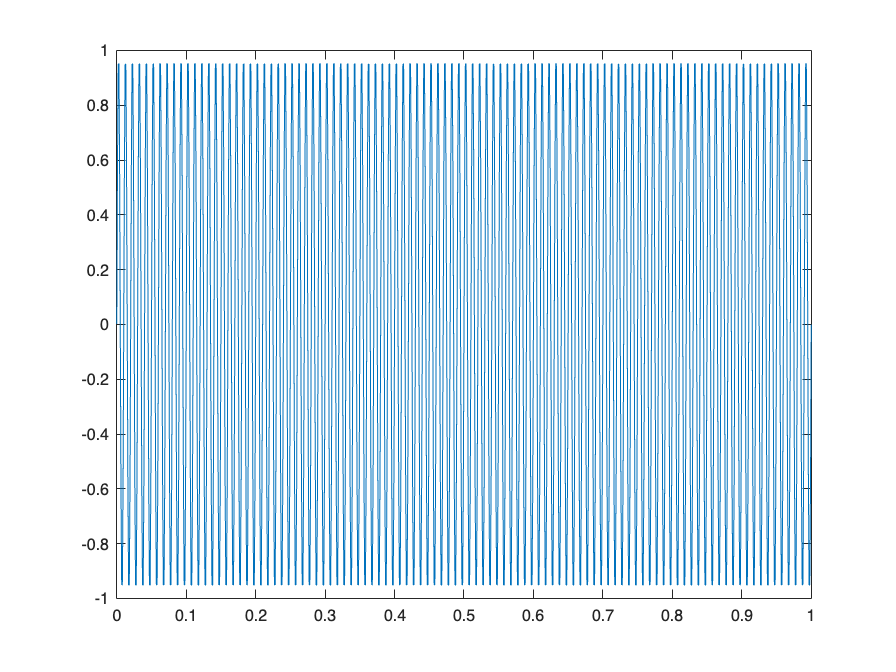

f1 = 100; %Hz
f2 =  120; %Hz
A = 1; % amplitude
t = [0:1/1000:1];
f_s = 1000;
d = 1 - 0; % duration


% f_s = n/(x2-x1) % f_s = n/duration = n/(x2-x1)
% t = [x1:1/f_s:(x2-1)]; 
% so in this case f_s = 1000 -> by reading t definition

% function [x]=generate_sine(frequency,A,fs,duration)
x1 = generate_sine(f1, A, f_s, d);

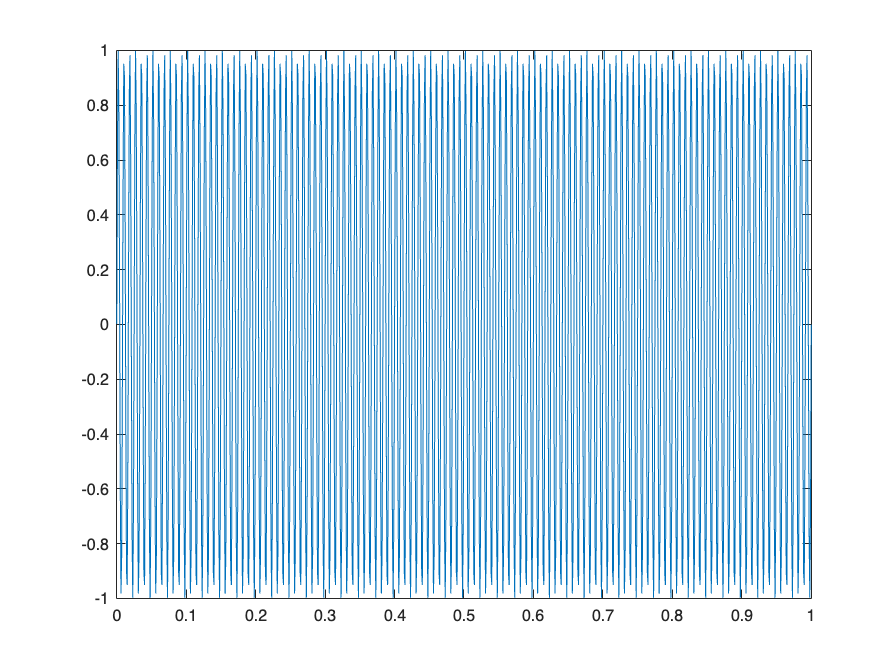

x2 = generate_sine(f2, A, f_s, d);


x3 = x1 + x2;

%function xn=addNoise(x, t, snr)
SNR = 10;
x3_noise = addNoise(x3,t,SNR);

**Apply the function periodogram.m to estimate the Power Spectral Density. **

% [Pxx,f] = periodogram(X,WINDOW,NFFT,...,FREQRANGE, Fs)
%       [pxx,f] = periodogram(x,window,f,fs)


**Use a rectangular window for comparing the results obtained setting N=500, 250, 75 samples. **

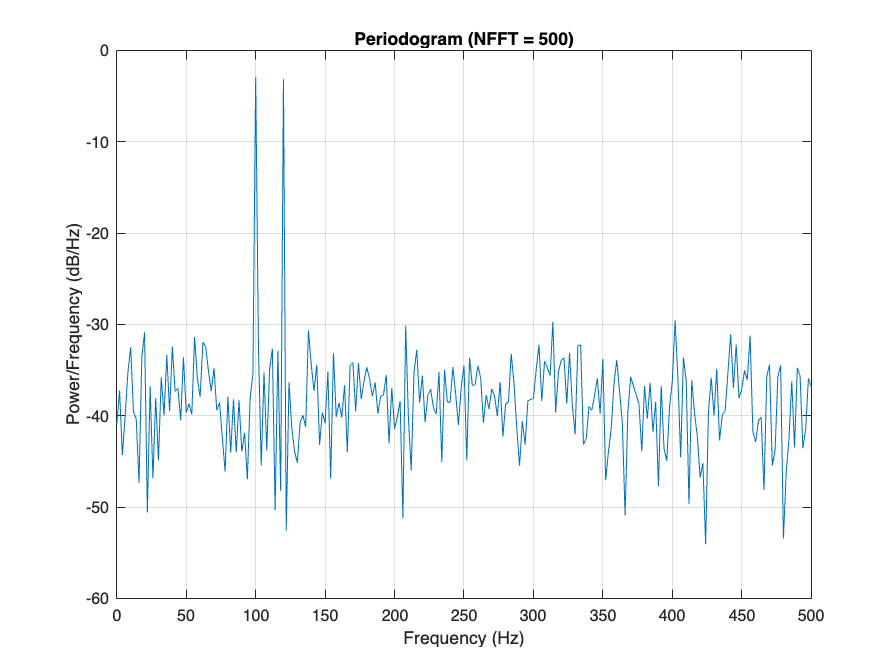

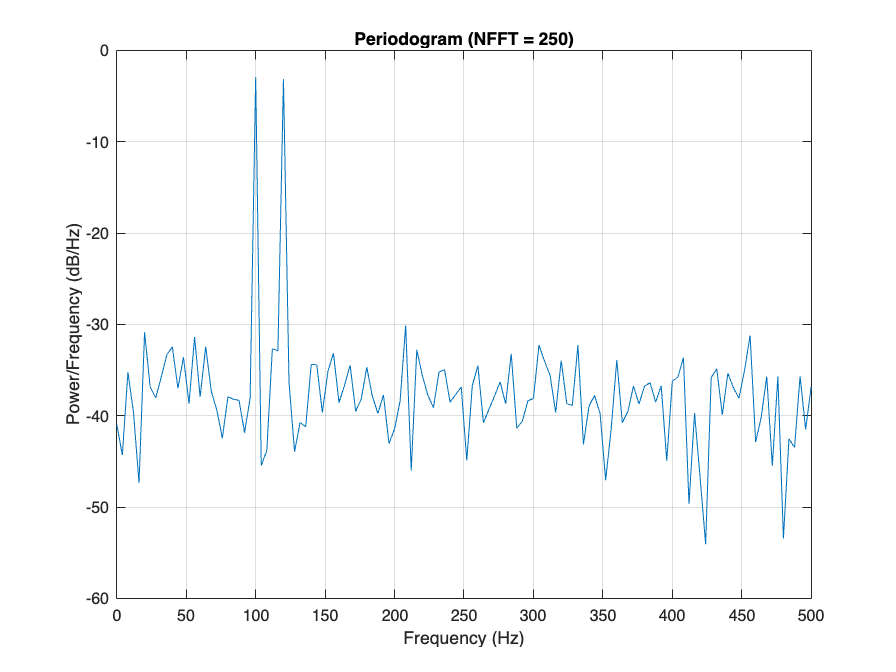

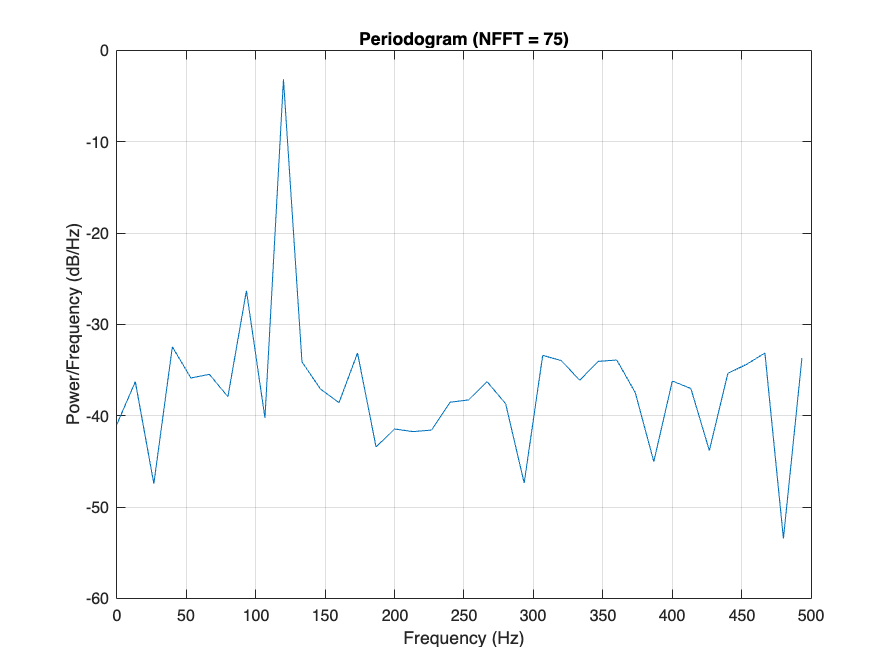

% Define the rectangular window function
rect_window = rectwin(length(x3_noise));

% Define different NFFT values
NFFT_values = [500, 250, 75];

% Initialize cells to save results
Pxx_results = cell(1, length(NFFT_values));
f_results = cell(1, length(NFFT_values));

% Loop over different NFFT values to calculate and plot the periodogram
for i = 1:length(NFFT_values)
    NFFT = NFFT_values(i); % Ottiene l'i-esimo valore di NFFT
    [Pxx, f] = periodogram(x3_noise, rect_window, NFFT, f_s);
    
    % Save the results in cells
    Pxx_results{i} = Pxx;
    f_results{i} = f;
    
    % View the results
    figure;
    plot(f, 10*log10(Pxx));
    title(['Periodogram (NFFT = ', num2str(NFFT), ')']);
    xlabel('Frequency (Hz)');
    ylabel('Power/Frequency (dB/Hz)');
    grid on;
end

**Use a hanning window for comparing the results obtained setting N=500, 250, 75 samples. **

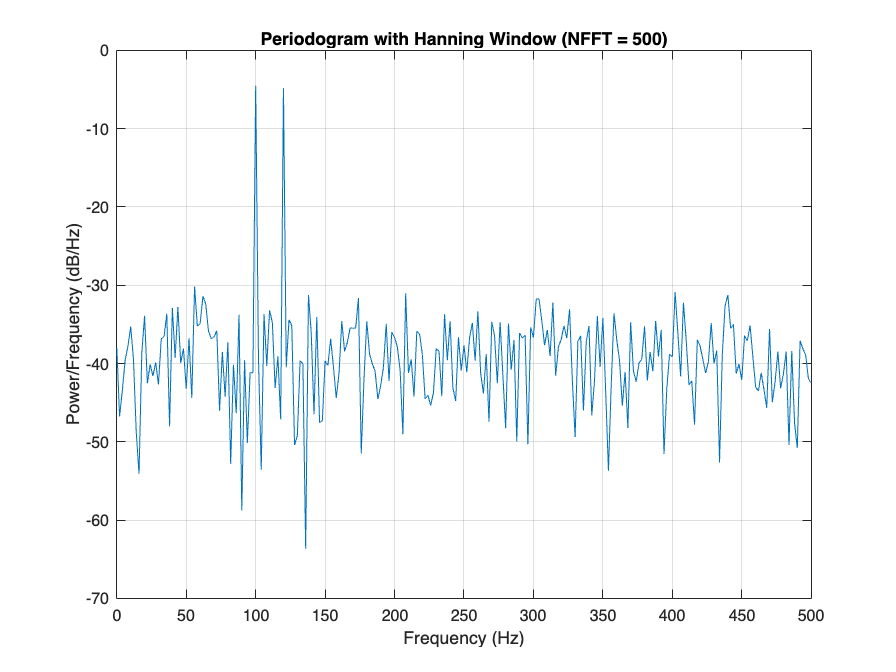

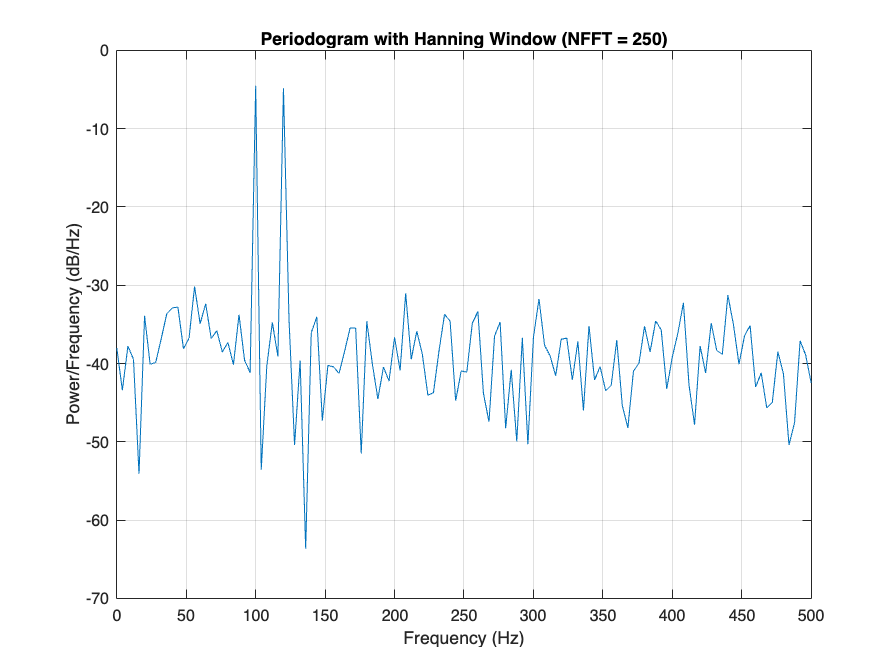

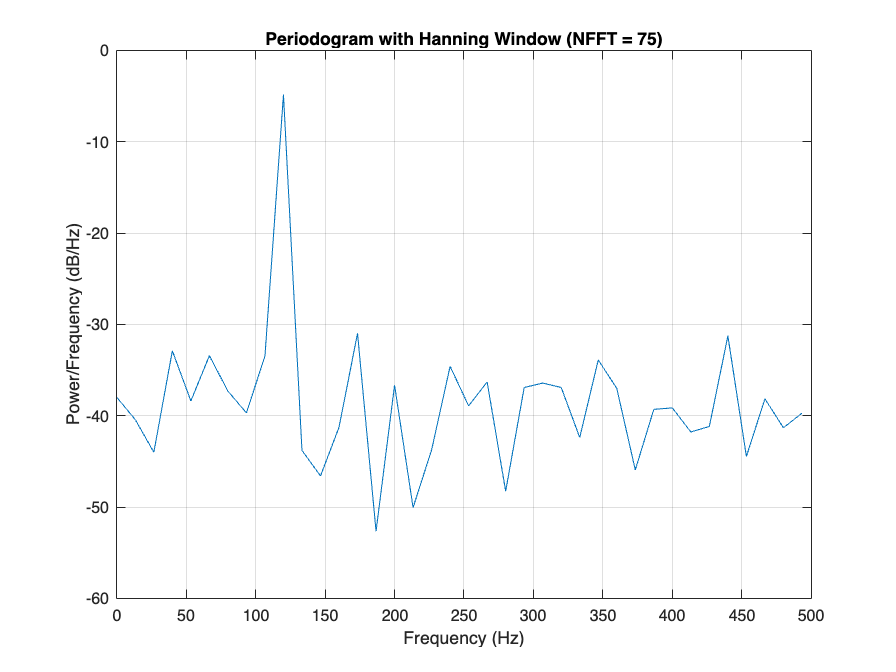

% Define the Hanning window function
hanning_window = hanning(length(x3_noise));

% Define different NFFT values
NFFT_values = [500, 250, 75];


% Initialize cells to save results
Pxx_han_results = cell(1, length(NFFT_values));
f_han_results = cell(1, length(NFFT_values));

% Loop over different NFFT values to calculate and plot the periodogram
for i = 1:length(NFFT_values)
    NFFT = NFFT_values(i); % Ottiene l'i-esimo valore di NFFT
    [Pxx, f] = periodogram(x3_noise, hanning_window, NFFT, f_s);
    
    % Save the results in cells
    Pxx_han_results{i} = Pxx;
    f_han_results{i} = f;
    
    % View the results
    figure;
    plot(f, 10*log10(Pxx));
    title(['Periodogram with Hanning Window (NFFT = ', num2str(NFFT), ')']);
    xlabel('Frequency (Hz)');
    ylabel('Power/Frequency (dB/Hz)');
    grid on;
end

**comparison between rectangular and hanning window**

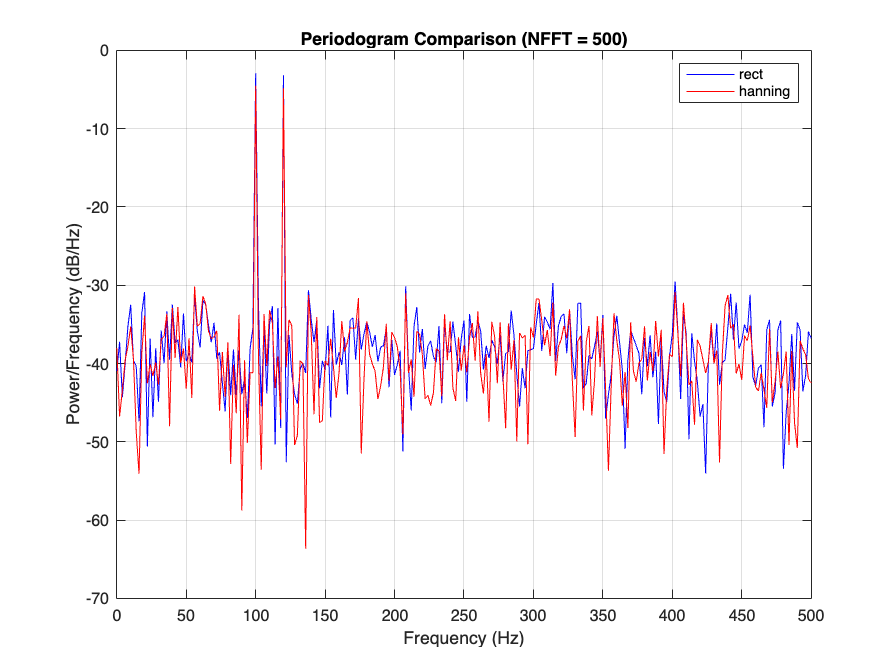

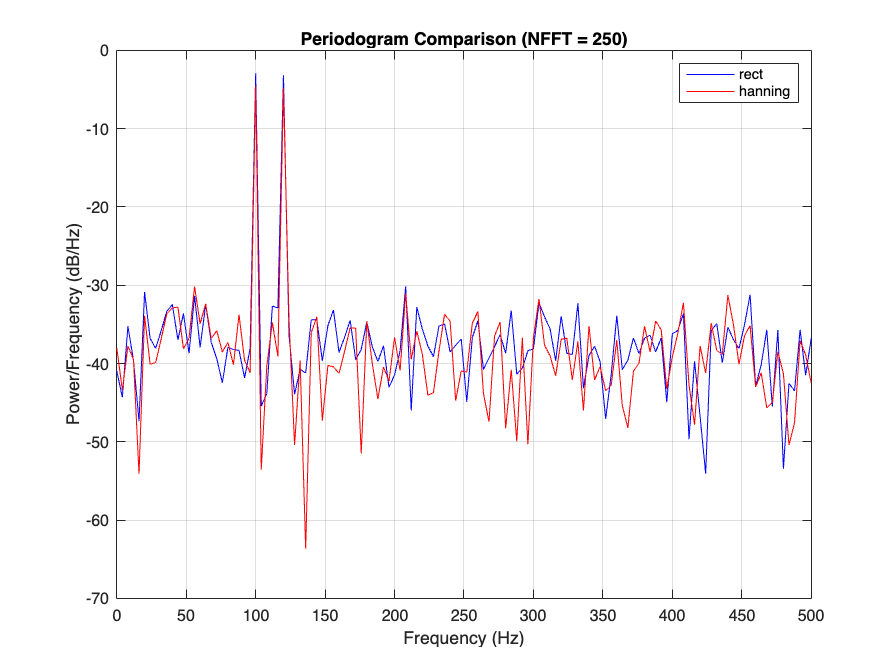

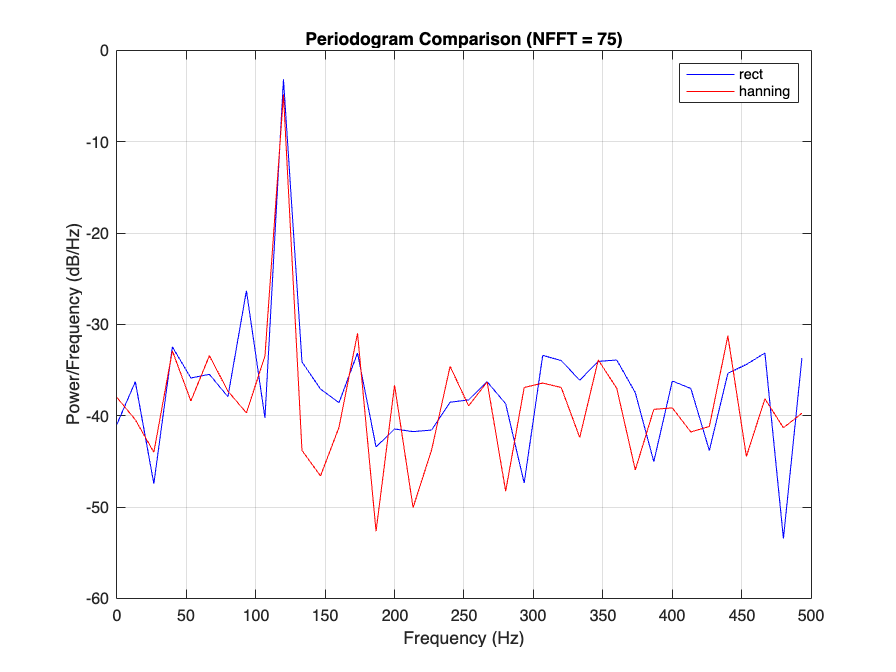


% Generate overlay plots for each value of NFFT
for i = 1:length(NFFT_values)
    figure;
    plot(f_results{i}, 10*log10(Pxx_results{i}), 'b', 'DisplayName', 'rect');
    hold on;
    plot(f_han_results{i}, 10*log10(Pxx_han_results{i}), 'r', 'DisplayName', 'hanning');
    title(['Periodogram Comparison (NFFT = ', num2str(NFFT_values(i)), ')']);
    xlabel('Frequency (Hz)');
    ylabel('Power/Frequency (dB/Hz)');
    legend;
    grid on;
    hold off;
end

**What changes to the variation of N and to the variation of the window type? **

Variation of N (NFFT values):

- Higher NFFT (e.g., 500): Provides better frequency resolution, meaning the ability to distinguish closely spaced frequency components improves. The spectral peaks are sharper and more defined.

- Lower NFFT (e.g., 75): Results in poorer frequency resolution, making it harder to distinguish between closely spaced frequencies. The spectral peaks are broader and less defined.

Variation of Window Type:

- Rectangular Window: Provides the best resolution in the frequency domain but has higher sidelobes, leading to spectral leakage. This means that energy from a frequency component spreads to adjacent frequencies.

- Hanning Window: Reduces sidelobe levels, which minimizes spectral leakage, but slightly worsens the frequency resolution compared to a rectangular window. The peaks are smoother and more reliable in terms of identifying the actual frequencies present in the signal.

**What changes if you apply zero-padding technique?**

Zero-padding involves appending zeros to the end of the time-domain signal before performing the FFT. This increases the number of FFT points without increasing the actual data length, effectively interpolating the FFT result and providing a denser frequency grid.

Changes Observed with Zero-Padding

- Zero-Padding with Higher NFFT: The primary benefit of zero-padding is the increased number of frequency bins in the FFT result, which provides a smoother and more detailed spectral estimate. The true frequency peaks remain at the same locations, but the interpolated points between peaks offer better insight into the shape of the spectrum.

- No Improvement in Resolution: It is important to note that zero-padding does not improve the actual frequency resolution. It only interpolates the spectrum, making it appear smoother and more continuous. The ability to resolve closely spaced frequency components remains unchanged.

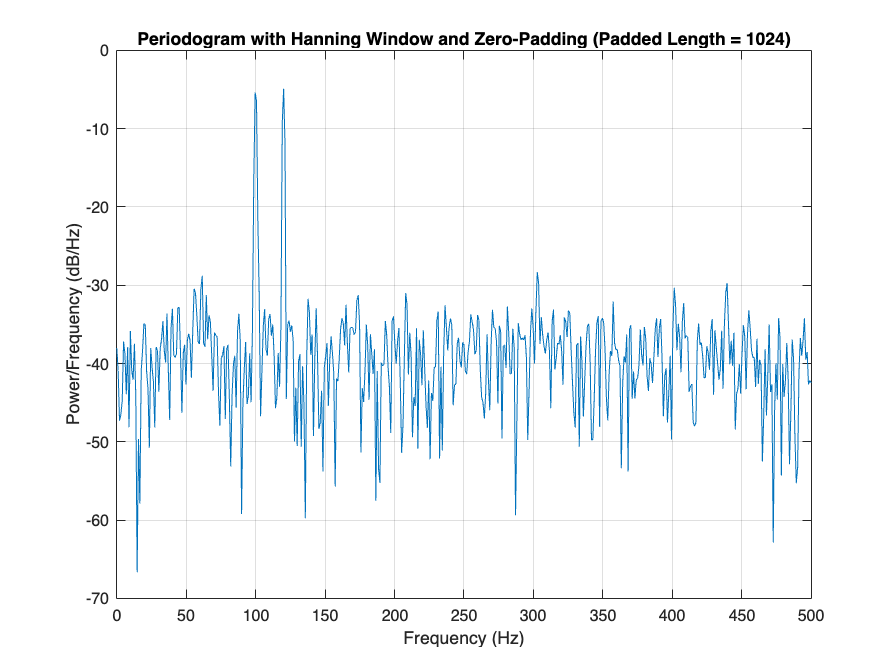

hanning_window = hanning(length(x3_noise));
padded_length=1024;

[Pxx, f] = periodogram(x3_noise, hanning_window, padded_length, f_s);

figure;
plot(f, 10*log10(Pxx));
title(['Periodogram with Hanning Window and Zero-Padding (Padded Length = ', num2str(padded_length), ')']);
xlabel('Frequency (Hz)');
ylabel('Power/Frequency (dB/Hz)');
grid on;

lo zero padding a 1024 è praticamente inutile dato che il segnale è lungo 1001.

magari potrei provare a fare zero padding finoo a 2048 e vedere che succede al segnale.

in teoria dovrebbe aumentare la risoluzione in frequenza, ma se i plot rimangono gli stessi allora il segnale di per se va bene così com'è e non ha senso incrementare zero padding.

Iteration: 1


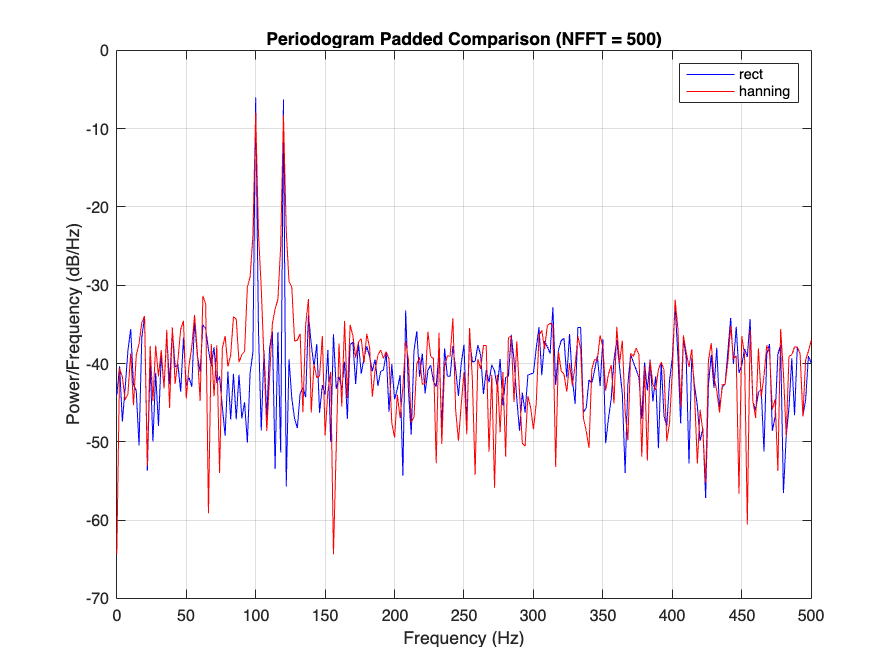

Iteration: 2


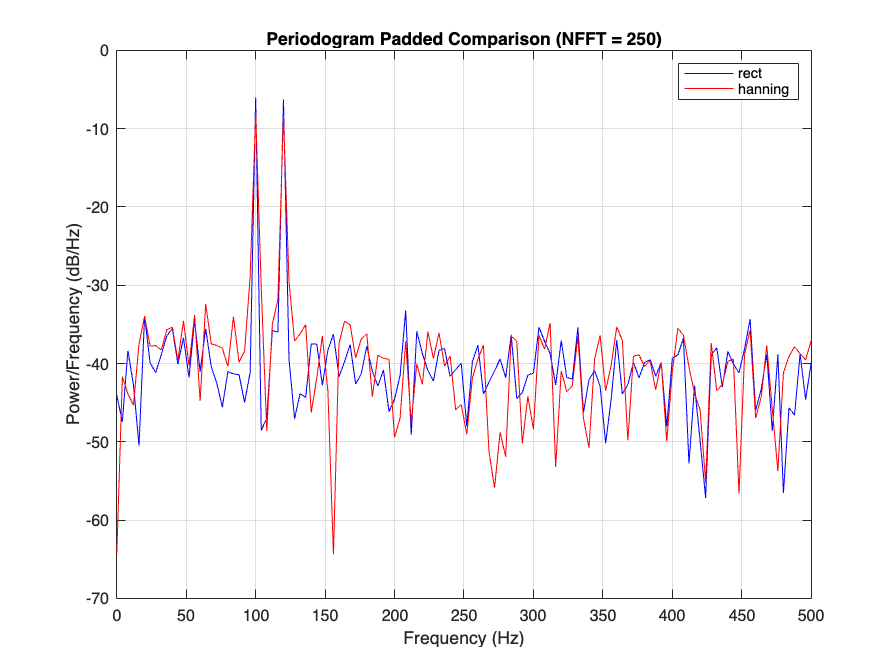

Iteration: 3


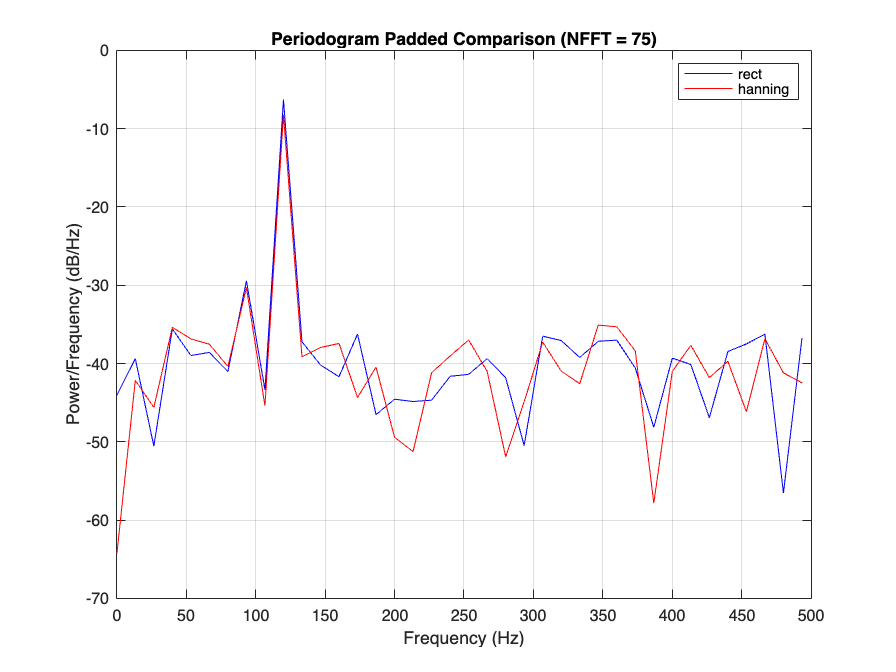

% Calculation of the number of zeros to add
num_zeros = 2048 - length(x3_noise);

%Adding zero padding to the end of the signal
x3_noise_padded = padarray(x3_noise, [num_zeros, 0], 'post');


%% rectangular windowing

% Define the rectangular window function
rect_window_padded = rectwin(length(x3_noise_padded));

% Define different NFFT values
NFFT_values = [500, 250, 75];

% Initialize cells to save results
Pxx_results_padded = cell(1, length(NFFT_values));
f_results_padded = cell(1, length(NFFT_values));

% Loop over different NFFT values to calculate and plot the periodogram
for i = 1:length(NFFT_values)
    NFFT = NFFT_values(i); % Ottiene l'i-esimo valore di NFFT
    [Pxx, f] = periodogram(x3_noise_padded, rect_window_padded, NFFT, f_s);
    
    % Save the results in cells
    Pxx_results_padded{i} = Pxx;
    f_results_padded{i} = f;
end


%% hanning windowing
% Define the Hanning window function
hanning_window_padded = hanning(length(x3_noise_padded));

% Define different NFFT values
NFFT_values = [500, 250, 75];


% Initialize cells to save results
Pxx_han_results_padded = cell(1, length(NFFT_values));
f_han_results_padded = cell(1, length(NFFT_values));

% Loop over different NFFT values to calculate and plot the periodogram
for i = 1:length(NFFT_values)
    NFFT = NFFT_values(i); % Ottiene l'i-esimo valore di NFFT
    [Pxx, f] = periodogram(x3_noise_padded, hanning_window_padded, NFFT, f_s);
    
    % Save the results in cells
    Pxx_han_results_padded{i} = Pxx;
    f_han_results_padded{i} = f;
end


% Plots compared

for i = 1:length(NFFT_values)
    disp(['Iteration: ', num2str(i)]);
    figure;
    plot(f_results_padded{i}, 10*log10(Pxx_results_padded{i}), 'b', 'DisplayName', 'rect');
    hold on;
    plot(f_han_results_padded{i}, 10*log10(Pxx_han_results_padded{i}), 'r', 'DisplayName', 'hanning');
    title(['Periodogram Padded Comparison (NFFT = ', num2str(NFFT_values(i)), ')']);
    xlabel('Frequency (Hz)');
    ylabel('Power/Frequency (dB/Hz)');
    legend;
    grid on;
    hold off;
end

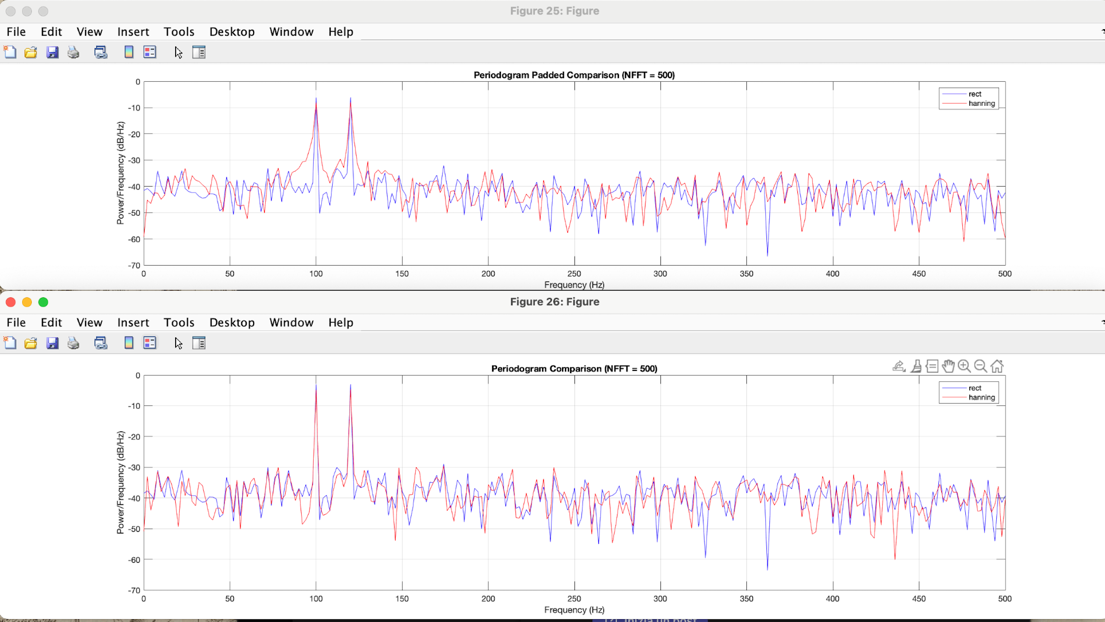

Visible Differences 

- Frequency Resolution:

- Top Graph (With Zero Padding): The frequency resolution is improved due to the addition of zero padding. This is evident from the higher density of data points along the frequency axis. The spectral components are more detailed and the peaks are more distinct.

- Bottom Graph (Without Zero Padding): The frequency resolution is lower. The spectral peaks are wider and less distinct.

- Noise Level and Spectral Details:

- Top Graph: With zero padding, the background noise level seems to be more uniformly distributed. The spectral details are more visible due to the higher frequency resolution.

- Bottom Graph: The noise level appears more varied and the spectral details are less prominent. This can make it harder to distinguish between noise and weak signals.

- Spectral Peaks:

- Top Graph: The peaks are narrower and well-defined. This is a result of the increased frequency resolution due to zero padding.

- Bottom Graph: The peaks are wider and less defined. The lower frequency resolution makes the peaks less distinct.